## Zadatak 3

1. Generisati tri klase dvodimenzionalnih oblika. Izabrati funkciju gustine verovatnoće oblika tako da klase budu  linearno separabilne.  

-  Za tako generisane oblike izvšiti projektovanje linearnog klasifikatora jednom od tri iterativne procedure. Rezultate prikazati u obliku matrice konfuzije. Detaljno opisati postupak klasifikacije. 

- Ponoviti prethodni postupak korišćenjem metode željenog izlaza. Analizirati uticaj elemenata u matrici željenih  izlaza na konačnu formu linearnog klasifikatora.

 2. Generisati dve klase dvodimenzionalnih oblika koje jesu seperabilne, ali ne linearno, pa isprojektovati kvadratni  klasifikator metodom po želji.

### Generisanje i prikaz podataka

Generisacemo podatke sa Gausovom raspodelom tako da su ocekivanja na dovoljno velikim rastojanjima a kovarijacione matrice dovoljno male da bi bile linearno separabilne.

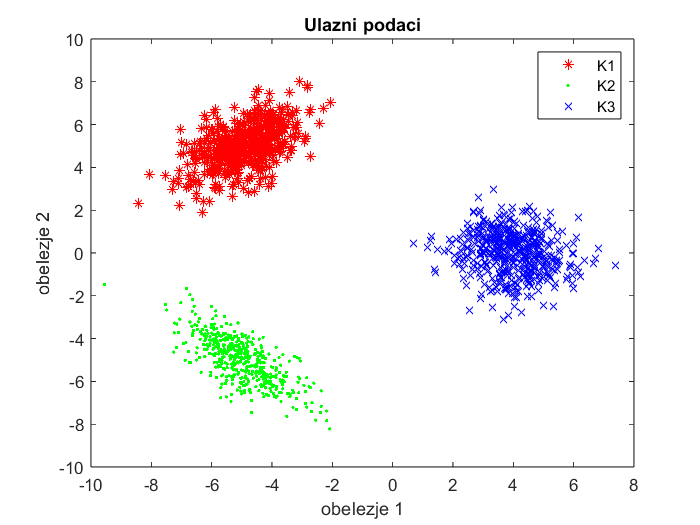

fig_id = 1;
N = 500;

M1 = [-5 5]';
S1 = [1 0.5; 0.5 1];
M2 = [-5 -5]';
S2 = [1 -0.7; -0.7 1];
M3 = [4 0]';
S3 = [1 -0.2; -0.2 1];


K1 = mvnrnd(M1,S1, N)';
K2 = mvnrnd(M2,S2, N)';
K3 = mvnrnd(M3,S3, N)';

figure(fig_id)
plot(K1(1,:),K1(2,:),'r*')
hold on;
plot(K2(1,:),K2(2,:),'g.')
hold on;
plot(K3(1,:),K3(2,:),'bx')
hold on;
title('Ulazni podaci')
xlabel('obelezje 1')
ylabel('obelezje 2')

legend('K1','K2','K3')
fig_id = fig_id+1;

### Podela podataka na test  obocavajuci skup

K1 = K1(:, randperm(size(K1, 2)));
K1_test = K1(:,1:150);
K1_train = K1(:,151:end);

K2 = K2(:, randperm(size(K2, 2)));
K2_test = K2(:,1:150);
K2_train = K2(:,151:end);

K3 = K3(:, randperm(size(K3, 2)));
K3_test = K3(:,1:150);
K3_train = K3(:,151:end);

### Projektovanje optimalnog linearnog klasifikatora

Koristicemo hold-out numericki metod, da bi nasa procena bila nepristrasna i da bismo izbegli kompjuterski zahtevno racunanje integrala.

Parametri klase i parametri V i v0 se racunaju nad obucavajucim skupom pomocu formula koje su dobijene tako da minimizuju kriterijumsku funkciju koja je u slucaju optimalnog linearnog klasifikatora funkcija verovatnoce greske u slucaju gausovski raspodeljenih oblika. Da bismo izbegli racunanje integrala formiramo prakticno grid u opsegu mogucih y vrednosti skupa koje imamo i nalazimo optimalno v0 za ovaj skup koje ne mora biti ( i cesto nije) globalni optimum ali dovoljno dobro radi.

Svi odbirci prve klase za koje je y1>-v0 su lose klasifikovani pa treba naci broj ovakvih odbiraka kao i broj odbiraka koji su iz druge klase i vazi y2<-v0.

Nakon sto smo nasli parametre V i v0 za sve vrednosti s, a zatim racunamo gresku nad test skupom za sve vrednosti s. Na kraju, bira se ono s koje minimicuje gresku sracunatu nad test skupom. Na samom kraju, plotuje se izgleda podataka i klasifikacona linija.

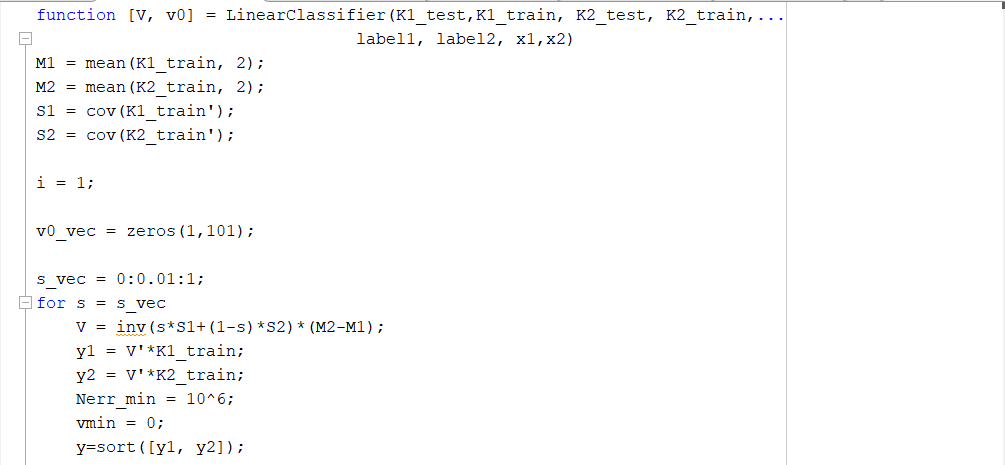

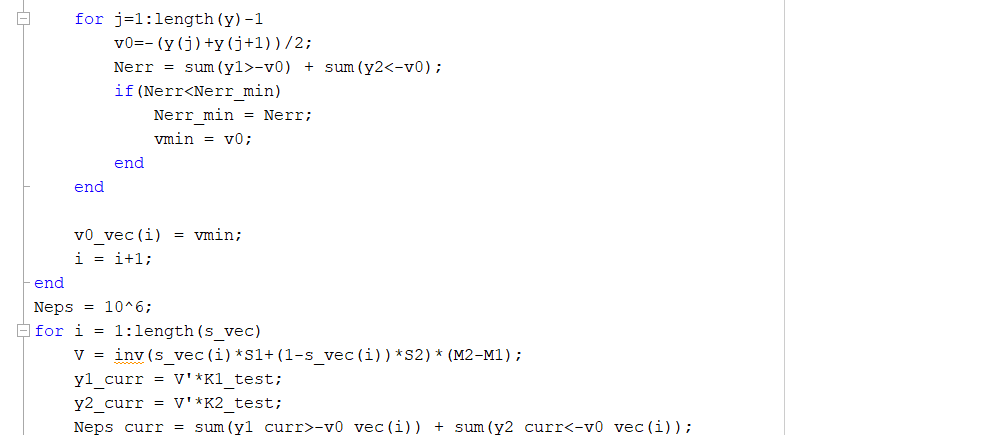

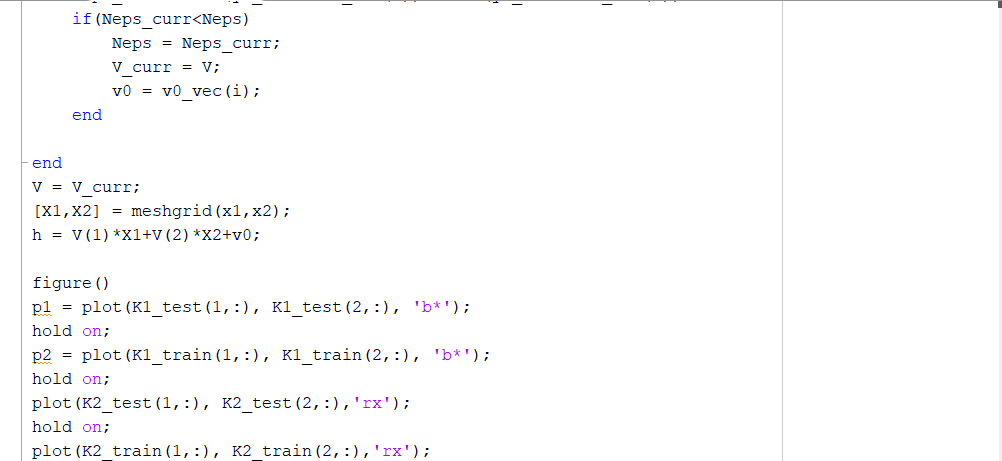

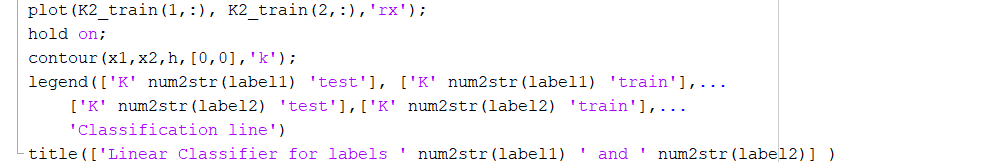

Ovaj klasifikator napravljen je za slucaj dve klase. S obzirom da mi imamo tri klase koristicemo deo po deo linearni klasifikator koji  formira klasifikacione linije za svake dve klase a zatim klasifikuje odbirke tako sto ih propusti kroz svaki od klasifikatora ( u ovom slucaju ih je 3 - izmedju 1 i 2, 2 i 3, 3 i 1) i klasifikuje odbirak u onu klasu koja je dobila najvise glasova za sta se koristi modus ta tri broja.

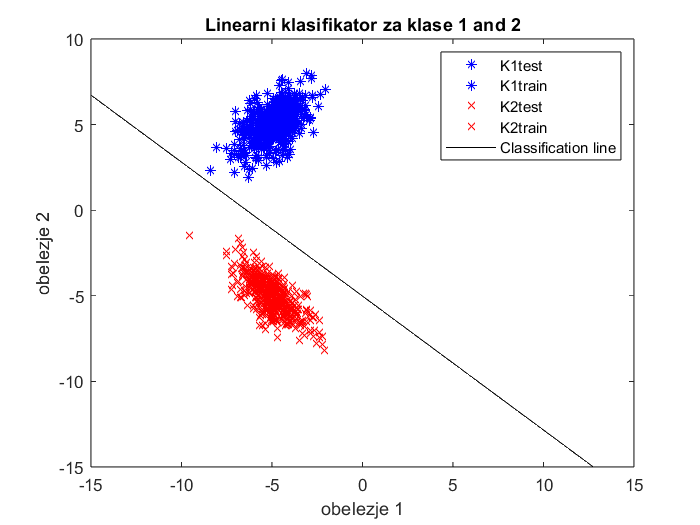

x_grid = -15:0.1:15;
y_grid = -15:0.1:10;
[V12,v012] = LinearClassifier(K1_test,K1_train, K2_test, K2_train,1,2,x_grid, y_grid,fig_id);

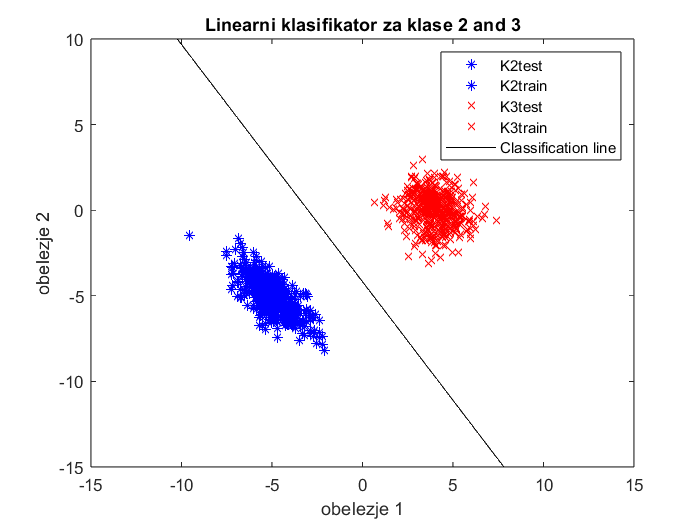

fig_id = fig_id+1;
[V23,v023] = LinearClassifier(K2_test,K2_train, K3_test, K3_train,2,3,x_grid,y_grid,fig_id);

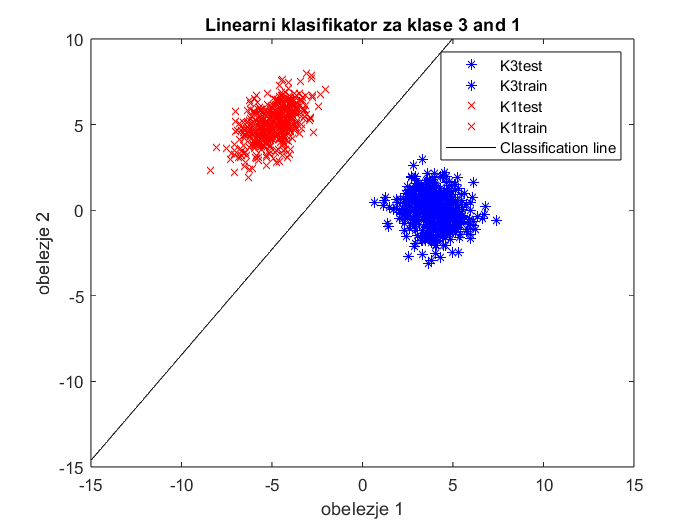

fig_id = fig_id+1;
[V31,v031] = LinearClassifier(K3_test,K3_train, K1_test, K1_train,3,1,x_grid,y_grid,fig_id);

fig_id = fig_id +1;

K_test = [K1_test, K2_test, K3_test];
y1 = zeros(1,length(K_test));
y2 = zeros(1,length(K_test));
y3 = zeros(1,length(K_test));
y_pred = zeros(1,length(K_test));
y_true = [ones(1,150), 2*ones(1,150), 3*ones(1,150)];
cond1 = V12'*K_test+v012>0;
y1(cond1) = 2;
y1(~cond1) = 1;
cond2 = V23'*K_test+v023>0;
y2(cond2) = 3;
y2(~cond2) = 2;
cond3 = V31'*K_test+v031>0;
y3(cond3) = 1;
y3(~cond3) = 3;

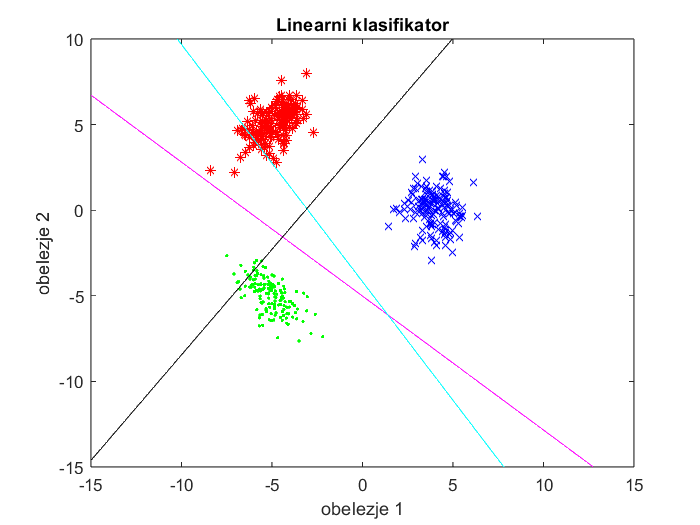

K = [K1, K2, K3];
[X1,X2] = meshgrid(x_grid,y_grid);
h12 = V12(1)*X1+V12(2)*X2+v012;
h23 = V23(1)*X1+V23(2)*X2+v023;
h31 = V31(1)*X1+V31(2)*X2+v031;

y_pred = mode([y1;y2;y3]);
figure(fig_id)
plot(K_test(1,y_pred==1),K_test(2,y_pred==1),'r*')
hold on;
plot(K_test(1,y_pred==2),K_test(2,y_pred==2),'g.')
hold on;
plot(K_test(1,y_pred==3),K_test(2,y_pred==3),'bx')
hold on;
contour(x_grid,y_grid,h12,[0,0],'m');
hold on;
contour(x_grid,y_grid,h23,[0,0],'c');
hold on;
contour(x_grid,y_grid,h31,[0,0],'k');
hold on;
no_mans_land = (y1~=y2 & y2~=y3 & y3~=y1);
title('Linearni klasifikator')
xlabel('obelezje 1')
ylabel('obelezje 2')

fig_id = fig_id+1;
disp('Broj elemenata u nicijoj zemlji')

Broj elemenata u nicijoj zemlji


disp(sum(no_mans_land))

     0



U opstem slucaju kod ovakvog klasifikatora je moguce dobiti deo ravni za koji nije moguce jednoznacno odrediti kojoj klasi pripada. S obizrom da su nasi ulazni podaci skroz linearno separabilni, ni jedan od podataka ne pripada ovom delu ravni, a konfuziona matrica je dijagonalna jer su svi odbirci potpuno svrstani u svoje klase.

C = confusionmat(y_true, y_pred);
disp(C)

   150     0     0
     0   150     0
     0     0   150



### Metod zeljenog izlaza

Odbirci prve klase se negiraju a odbirci druge klase ostaju isti cime dobijamo novi ulaz u nas model. Postavljamo kriterijumsku funkciju koju minimizujemo cime dobijamo koeficijent kojim treba pomnoziti novi ulaz modela da bi sto vise odbiraka pomnozeno tezinom bilo pozitivno. Ta tezina kojom mnozimo odbirke sastoji se iz parametara V i v0 koriscenih kod linearnog klasifikatora a uslov pozitivnosti zamenjuje uslov znaka kojim se klasifikuju odbirci u slucaju linearnog klasifikatora. Tezina se nalazi metodom pseudoinverzije.Kriterijumska funkcija koja se minimizuje je srednje kvadratna greska.

Vektor Gama nam omogucava da nekim odbircima damo vise znacaja. Mnozenje svih elemenata Gama nekom konstantnom nece nista promeniti jer idalje svi elementi imaju jednak znacaj. Postavljanjem Gama na vecu vrednost za neku klasu pomera klasifikacionu liniju dalje od odbiraka te klase jer time govorimo klasifikatoru da nam je bitnije da ta klasa bude tacno svrstana nego ostale. Takodje, mozemo za neke konkretne odbirke da postavimo  Gama na vecu vrednost, na primer ako imamo odbirke koji se nalaze previse blizu granice klasifikacije, mozemo njima dati vecu tezinu jer ako uspemo njih da odvojimo uspecemo i ostale cime pomazemo klasifikatoru.

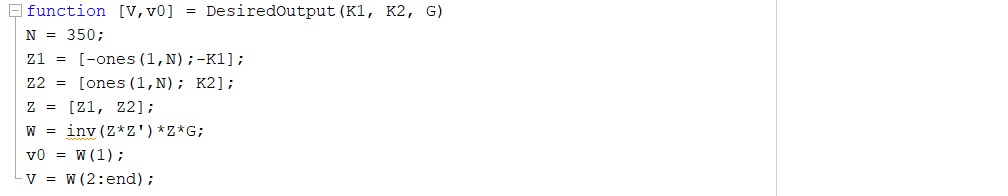

#### Gama = ones(2N,1)

Prikaz klasifikatora

G = ones(2*350, 1);
[V12,v012] = DesiredOutput(K1_train,K2_train,G);
[V23,v023] = DesiredOutput(K2_train, K3_train,G);
[V31,v031] = DesiredOutput(K3_train, K1_train,G);

Racunanje vrednosti izlaza:

K_test = [K1_test, K2_test, K3_test];
y1 = zeros(1,length(K_test));
y2 = zeros(1,length(K_test));
y3 = zeros(1,length(K_test));

y_true = [ones(1,150), 2*ones(1,150), 3*ones(1,150)];
cond1 = V12'*K_test+v012>0;
y1(cond1) = 2;
y1(~cond1) = 1;
cond2 = V23'*K_test+v023>0;
y2(cond2) = 3;
y2(~cond2) = 2;
cond3 = V31'*K_test+v031>0;
y3(cond3) = 1;
y3(~cond3) = 3;
y_pred = mode([y1;y2;y3]);

Uporedni prikaz metode zeljenog izlaza i prethodnog metoda

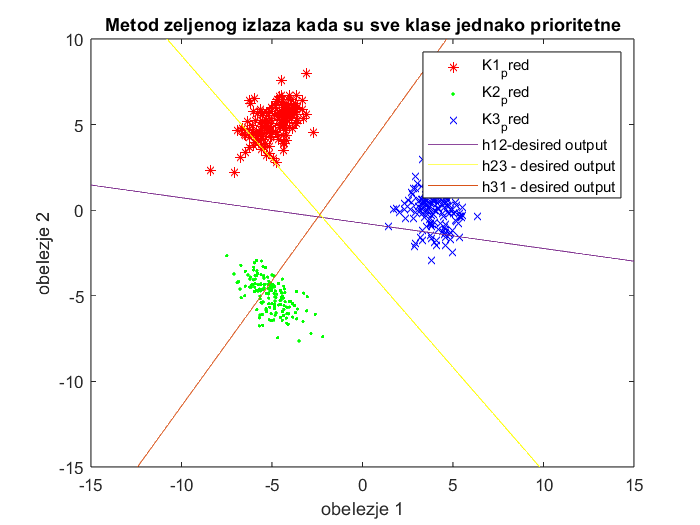

K = [K1, K2, K3];
[X1,X2] = meshgrid(x_grid,y_grid);
h12_d = V12(1)*X1+V12(2)*X2+v012;
h23_d = V23(1)*X1+V23(2)*X2+v023;
h31_d = V31(1)*X1+V31(2)*X2+v031;


figure(fig_id)
plot(K_test(1,y_pred==1),K_test(2,y_pred==1),'r*')
hold on;
plot(K_test(1,y_pred==2),K_test(2,y_pred==2),'g.')
hold on;
plot(K_test(1,y_pred==3),K_test(2,y_pred==3),'bx')
hold on;
contour(x_grid,y_grid,h12_d,[0,0],'EdgeColor',	[0.4940 0.1840 0.5560]);
hold on;
contour(x_grid,y_grid,h23_d,[0,0],'y');
hold on;
contour(x_grid,y_grid,h31_d,[0,0],'EdgeColor',	[0.8500 0.3250 0.0980]);
hold on;
xlabel('obelezje 1')
ylabel('obelezje 2')
title('Metod zeljenog izlaza kada su sve klase jednako prioritetne')
legend('K1_pred','K2_pred','K3_pred', 'h12-desired output','h23 - desired output', 'h31 - desired output')

fig_id = fig_id+1;

Primecujemo da su klasifikacione linije postavljene tako da su otprilike izmedju klasa.

Konfuziona matrica:

C = confusionmat(y_true, y_pred);
disp(C)

   150     0     0
     0   150     0
     0     0   150



Svi odbirci su dobro svrstani.

#### Gama = [ones(N,1),;2*ones(N,1)] za K12,  [2* ones(N,1) ;ones(N,1)] za K23, ones(2*N,1) za K13

####  -> kazemo da su odbirci druge klase 2*bitniji 

[V12,v012] = DesiredOutput(K1_train,K2_train,[ones(350, 1);2*ones(350, 1)]);
[V23,v023] = DesiredOutput(K2_train, K3_train,[2*ones(350, 1);ones(350, 1)]);
[V31,v031] = DesiredOutput(K3_train, K1_train,ones(2*350, 1));

Racunanje vrednosti izlaza:

K_test = [K1_test, K2_test, K3_test];
y1 = zeros(1,length(K_test));
y2 = zeros(1,length(K_test));
y3 = zeros(1,length(K_test));

y_true = [ones(1,150), 2*ones(1,150), 3*ones(1,150)];
cond1 = V12'*K_test+v012>0;
y1(cond1) = 2;
y1(~cond1) = 1;
cond2 = V23'*K_test+v023>0;
y2(cond2) = 3;
y2(~cond2) = 2;
cond3 = V31'*K_test+v031>0;
y3(cond3) = 1;
y3(~cond3) = 3;
y_pred = mode([y1;y2;y3]);

Uporedni prikaz metode zeljenog izlaza za prethodno G gde su svi jednako bitni, i novo G za koje su odbirci klase 2 bitniji.

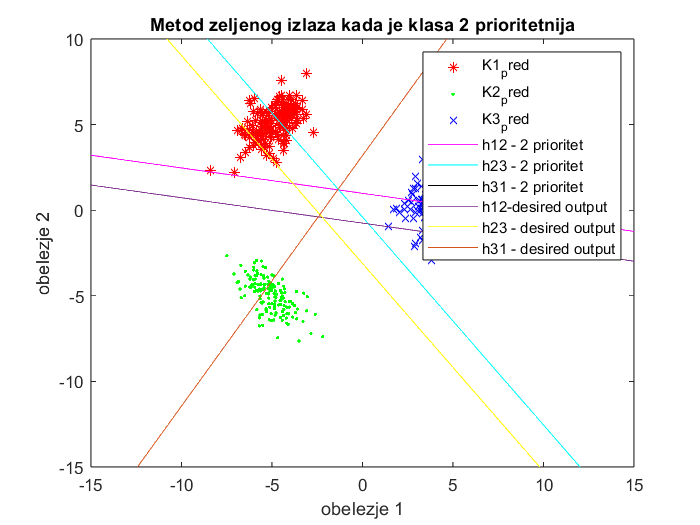

K = [K1, K2, K3];
[X1,X2] = meshgrid(x_grid,y_grid);
h12_d_1 = V12(1)*X1+V12(2)*X2+v012;
h23_d_1 = V23(1)*X1+V23(2)*X2+v023;
h31_d_1 = V31(1)*X1+V31(2)*X2+v031;


figure(fig_id)
plot(K_test(1,y_pred==1),K_test(2,y_pred==1),'r*')
hold on;
plot(K_test(1,y_pred==2),K_test(2,y_pred==2),'g.')
hold on;
plot(K_test(1,y_pred==3),K_test(2,y_pred==3),'bx')
hold on;
contour(x_grid,y_grid,h12_d_1,[0,0],'m');
hold on;
contour(x_grid,y_grid,h23_d_1,[0,0],'c');
hold on;
contour(x_grid,y_grid,h31_d_1,[0,0],'k');
hold on;
contour(x_grid,y_grid,h12_d,[0,0],'EdgeColor',	[0.4940 0.1840 0.5560]);
hold on;
contour(x_grid,y_grid,h23_d,[0,0],'y');
hold on;
contour(x_grid,y_grid,h31_d,[0,0],'EdgeColor',	[0.8500 0.3250 0.0980]);
hold on;
xlabel('obelezje 1')
ylabel('obelezje 2')
title('Metod zeljenog izlaza kada je klasa 2 prioritetnija')
legend('K1_pred','K2_pred','K3_pred','h12 - 2 prioritet','h23 - 2 prioritet','h31 - 2 prioritet', 'h12-desired output','h23 - desired output', 'h31 - desired output')

fig_id = fig_id+1;

Primetimo da su se sada obe klasifikacione linije u cijoj konstrukciji ucestvuje klasa 2 (zelena) pomerile dalje od nje a blize drugim dvema klasama dok je treca klasifikaciona linija ostala ista.

Konfuziona matrica:


C = confusionmat(y_true, y_pred);
disp(C)

   150     0     0
     0   150     0
     0     0   150



#### Gama = [1.5*ones(N,1),;ones(N,1)] za K12, ones(2*N,1) za K23, [ ones(N,1) ;1.5*ones(N,1)] za K31 

#### -> kazemo da su odbirci prve klase 1,5* bitniji

[V12,v012] = DesiredOutput(K1_train,K2_train,[1.5*ones(350, 1);ones(350, 1)]);
[V23,v023] = DesiredOutput(K2_train, K3_train,ones(2*350, 1));
[V31,v031] = DesiredOutput(K3_train, K1_train,[ones(350, 1);1.5*ones(350, 1)]);

Racunanje vrednosti izlaza:

K_test = [K1_test, K2_test, K3_test];
y1 = zeros(1,length(K_test));
y2 = zeros(1,length(K_test));
y3 = zeros(1,length(K_test));

y_true = [ones(1,150), 2*ones(1,150), 3*ones(1,150)];
cond1 = V12'*K_test+v012>0;
y1(cond1) = 2;
y1(~cond1) = 1;
cond2 = V23'*K_test+v023>0;
y2(cond2) = 3;
y2(~cond2) = 2;
cond3 = V31'*K_test+v031>0;
y3(cond3) = 1;
y3(~cond3) = 3;
y_pred = mode([y1;y2;y3]);

Uporedni prikaz metode zeljenog izlaza za prethodno G gde su svi jednako bitni, i novo G za koje su odbirci klase 2 bitniji.

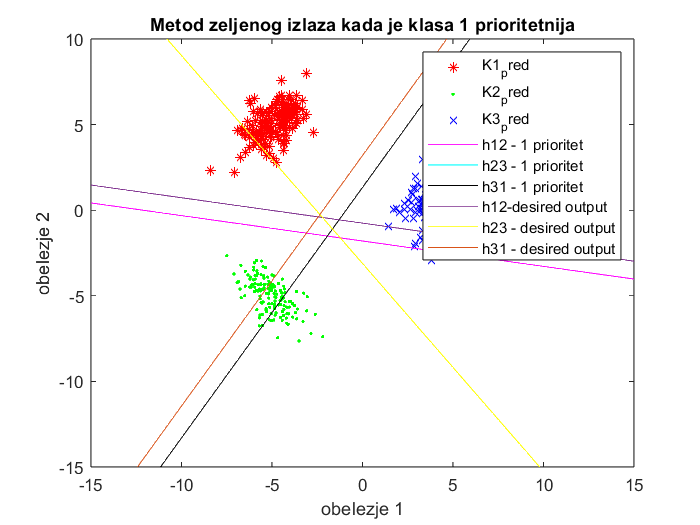

K = [K1, K2, K3];
[X1,X2] = meshgrid(x_grid,y_grid);
h12_d_1 = V12(1)*X1+V12(2)*X2+v012;
h23_d_1 = V23(1)*X1+V23(2)*X2+v023;
h31_d_1 = V31(1)*X1+V31(2)*X2+v031;


figure(fig_id)
plot(K_test(1,y_pred==1),K_test(2,y_pred==1),'r*')
hold on;
plot(K_test(1,y_pred==2),K_test(2,y_pred==2),'g.')
hold on;
plot(K_test(1,y_pred==3),K_test(2,y_pred==3),'bx')
hold on;
contour(x_grid,y_grid,h12_d_1,[0,0],'m');
hold on;
contour(x_grid,y_grid,h23_d_1,[0,0],'c');
hold on;
contour(x_grid,y_grid,h31_d_1,[0,0],'k');
hold on;
contour(x_grid,y_grid,h12_d,[0,0],'EdgeColor',	[0.4940 0.1840 0.5560]);
hold on;
contour(x_grid,y_grid,h23_d,[0,0],'y');
hold on;
contour(x_grid,y_grid,h31_d,[0,0],'EdgeColor',	[0.8500 0.3250 0.0980]);
hold on;
xlabel('obelezje 1')
ylabel('obelezje 2')
title('Metod zeljenog izlaza kada je klasa 1 prioritetnija')
legend('K1_pred','K2_pred','K3_pred','h12 - 1 prioritet','h23 - 1 prioritet','h31 - 1 prioritet', 'h12-desired output','h23 - desired output', 'h31 - desired output')

fig_id = fig_id+1;

Primetimo da su se sada obe klasifikacione linije u cijoj konstrukciji ucestvuje klasa 1 (crvena) pomerile dalje od nje a blize drugim dvema klasama dok je druga klasifikaciona linija ostala ista.

Konfuziona matrica:

C = confusionmat(y_true, y_pred);
disp(C)

   150     0     0
     0   150     0
     0     0   150



### Nelinearno separabilni podaci i kvadratni klasifikator

Ideja kod kvadratnog klasifikatora je da od nelinearne funkcije obelezja dobijemo linearnu funkciju od novonapravljenih obelezja. Ostali postupak je isti kao kod predjasnjeg klasifikatora. S obzirom da nam ni jedno obelezje nije bitnije koristicemo Gama sa istim prioritetima za sve.

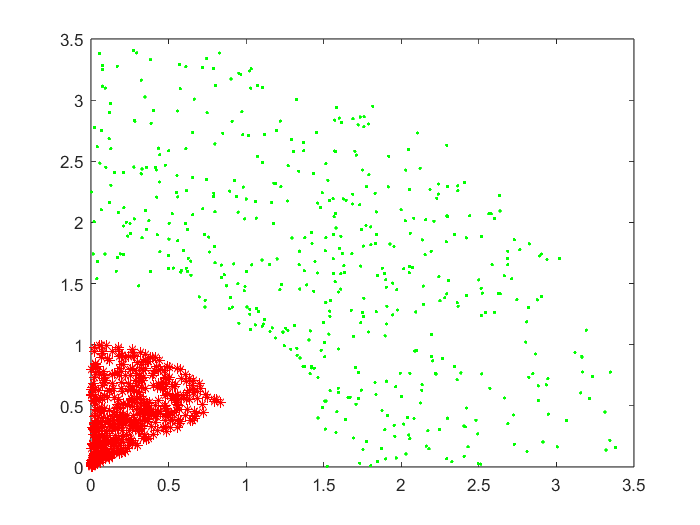

N = 500;
x = rand(1,500)*10-5;
rho = rand(1,500);
theta = rand(1,500)*pi/3;

K1 = [rho.*sin(theta);rho.*cos(theta)];

rho = rand(1,500)*2+1.5;
theta = rand(1,500)*pi/2;

K2 = [rho.*sin(theta);rho.*cos(theta)];

figure()
plot(K1(1,:),K1(2,:),'r*')
hold on;
plot(K2(1,:),K2(2,:),'g.')
hold on;

K1 = K1(:, randperm(size(K1, 2)));
K1_test = K1(:,1:150);
K1_train = K1(:,151:end);

K2 = K2(:, randperm(size(K2, 2)));
K2_test = K2(:,1:150);
K2_train = K2(:,151:end);

[V,v0] = QuadraticClassifier(K1_train,K2_train,ones(2*350, 1));

Racunanje vrednosti izlaza:

K_test = [K1_test, K2_test];

y_true = [ones(1,150), 2*ones(1,150)];
X = [K_test(1,:).^2 ;K_test(2,:).^2;K_test(1,:).*(K_test(2,:));K_test];
h = V'*X+v0>0;
y_pred = zeros(1,length(X));
y_pred(h) = 2;
y_pred(~h) = 1;


Uporedni prikaz metode zeljenog izlaza za prethodno G gde su svi jednako bitni, i novo G za koje su odbirci klase 2 bitniji.

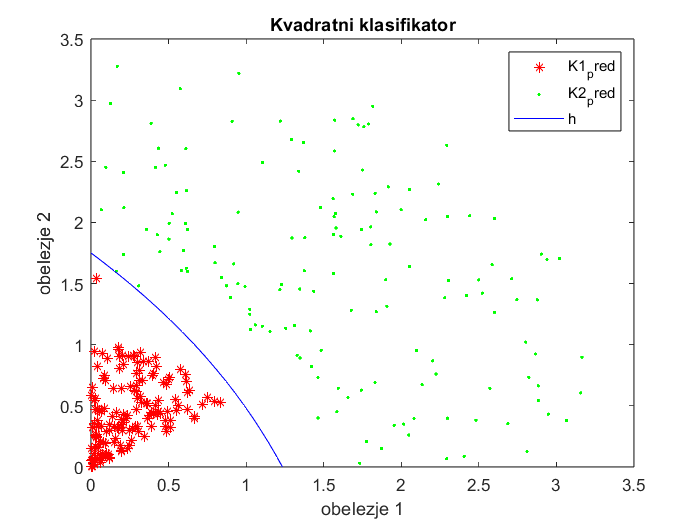

K = [K1, K2];
x_grid = 0:0.1:3.5;
y_grid = 0:0.1:3.5;
[X1,X2] = meshgrid(x_grid,y_grid);
h = v0+V(1)*(X1.^2)+V(2)*(X2.*2)+V(3).*(X1.*X2)+V(4)*(X1)+V(5)*(X2);

figure(fig_id)
plot(K_test(1,y_pred==1),K_test(2,y_pred==1),'r*')
hold on;
plot(K_test(1,y_pred==2),K_test(2,y_pred==2),'g.')
hold on;
contour(x_grid,y_grid,h,[0,0],'b');
xlabel('obelezje 1')
ylabel('obelezje 2')
title('Kvadratni klasifikator')
legend('K1_pred','K2_pred','h')

fig_id = fig_id +1;

Konfuziona matrica:

C = confusionmat(y_true, y_pred);
disp(C)

   150     0
     1   149

